# **ADT Localization**

***(Autonomous Vehicle Localization Using Onboard Sensors and HD-Geolocated Maps [MATLAB Project #20] - Spring 2024 Semester)***

[***Project Link***](https://github.com/Hazem-M-Abdelaziz/Autonomous-Vehicle-Localization-Using-Onboars-Sensor-and-HD-Geolocated-Maps-Project-Solution)

**Presented by: **

- Hazem Mohsen Abdelaziz 

- Yousra Adly Deifallah

**Under Supervision of:**

-  Prof. Dr. Mohamed Ibrahim Awad (Mechatronics Head Faculty of Engineering - Ain Shams University).

## **Load Data, Run Model & Prepare Camera Frames**

*Firstly, make sure you're in the directory of the Project Specially in the ADT Localization Folder. *

*This Section will Open the ADT Localization Simulink Model, load pose (X, Y, Yaw) data required for the Vehicle, set the parameters of Camera, Lidar, GPS, IMU, INS sensors and the Scene sampling time. Finally it will run the model to get the sensors output in the workspace (Results). *

%Open Simukink Model for data analysis and Loccalization 
open_system('D:\GP-Github\ADTLocalization\ADT_SimulinkModel.slx'); %Add the path of the ADTSimulinkModel

%Load setpoints for scene components and set the sensors Parameters 
variablesInitialization; 

%Run Simulink Model and Extract output
Results = sim('ADT_SimulinkModel');

%Convert video to frames 
convertVideoToFrames; %warning if the images folders exists 

Frames are stored in the folder


## **Visualize Ground Truth Pose of the Vehicle on US City Block Map**

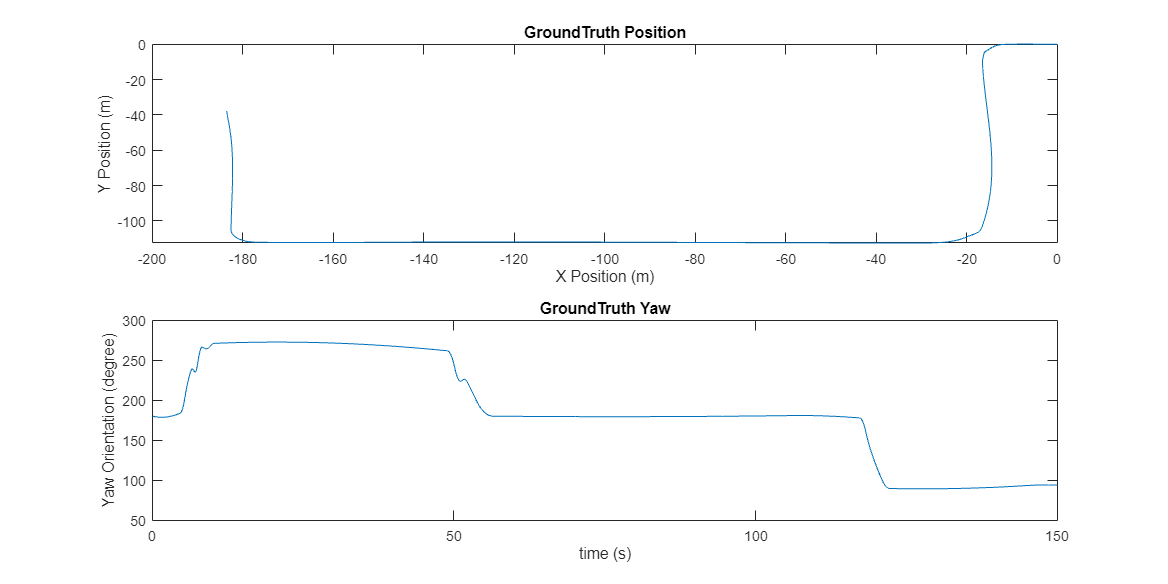

%Visualize groundtruth Position and Orientation data.
figure;
figure('Position', [50, 50, 2000, 1000]); % [left bottom width height]

%Creating subplots
subplot(2, 1, 1);
plot(refX, refY);
xlabel('X Position (m)');
ylabel('Y Position (m)');
title('GroundTruth Position');
 
subplot(2, 1, 2);
plot(timeVector, refYaw);
xlabel('time (s)');
ylabel('Yaw Orientation (degree)');
title('GroundTruth Yaw');

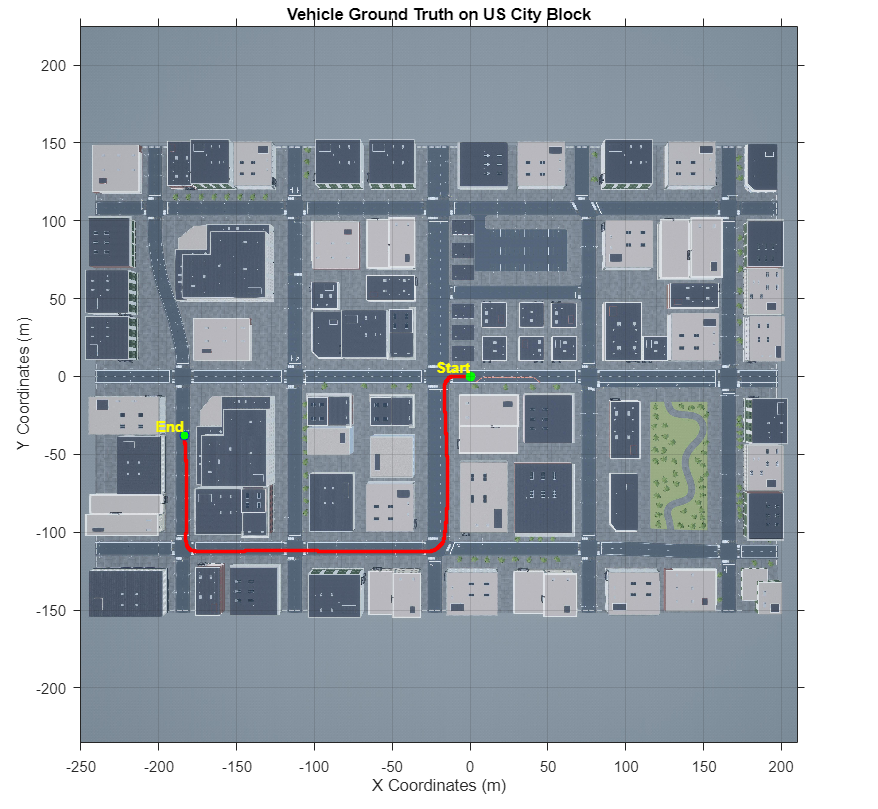

%Visualize the Ground Truth Position on US City Block Map
data = load('sim3d_SpatialReferences.mat');
spatialRef = data.spatialReference.USCityBlock;

figure;
fileName = 'sim3d_USCityBlock.jpg';
imshow(fileName,spatialRef);
set(gca,'YDir','normal')
xlabel('X Coordinates (m)')
ylabel('Y Coordinates (m)')

%Plot the position data
hold on;
plot(refX, refY, 'ro', 'MarkerSize', 2, 'MarkerFaceColor', 'r');

plot(refX(1), refY(1), 'go', 'MarkerSize', 6, 'MarkerFaceColor', 'g'); % Start point
text(refX(1), refY(1), 'Start', 'VerticalAlignment', 'bottom', 'HorizontalAlignment', 'right', 'FontSize', 10, 'FontWeight', 'bold', 'Color', 'y');

plot(refX(end), refY(end), 'bo', 'MarkerSize', 6, 'MarkerFaceColor', 'g'); % End point
text(refX(end), refY(end), 'End', 'VerticalAlignment', 'bottom', 'HorizontalAlignment', 'right', 'FontSize', 10, 'FontWeight', 'bold', 'Color', 'y');


title('Vehicle Ground Truth on US City Block');
grid on;

## **IMU/INS Localization Model**

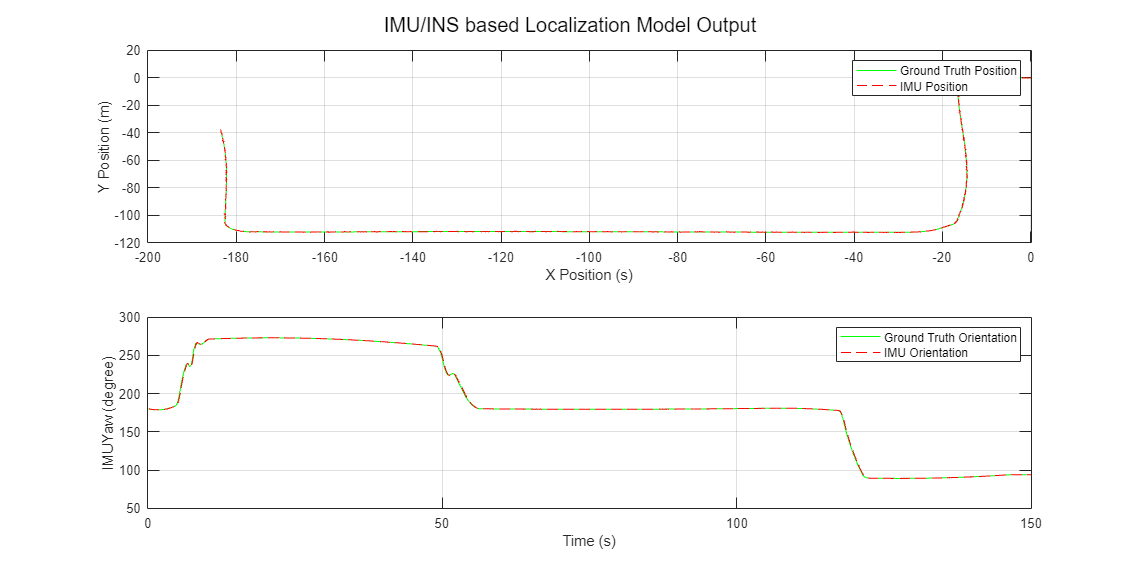

%Reshape IMU Estimated Pose 
%IMUX = squeeze(Results.IMUX.Data(2:end));
%IMUY = squeeze(Results.IMUY.Data(2:end));
%IMUYaw = rad2deg(squeeze(Results.IMUYaw.Data(2:end))) + refYaw(1);

%Plot Ground Truth Pose vs. IMU/INS Estimated Pose
figure;
figure('Position', [50, 50, 2000, 1000]); % [left bottom width height]

subplot(2, 1, 1);
plot(refX, refY, 'g');
hold on;
plot(IMUX, IMUY, 'r--');
xlabel('X Position (s)');
ylabel('Y Position (m)');
legend('Ground Truth Position', 'IMU Position');
grid on;

subplot(2, 1, 2);
plot(timeVector, refYaw, 'g');
hold on;
plot(timeVector, IMUYaw, 'r--');
xlabel('Time (s)');
ylabel('IMUYaw (degree)');
legend('Ground Truth Orientation', 'IMU Orientation');
grid on;
sgtitle('IMU/INS based Localization Model Output');

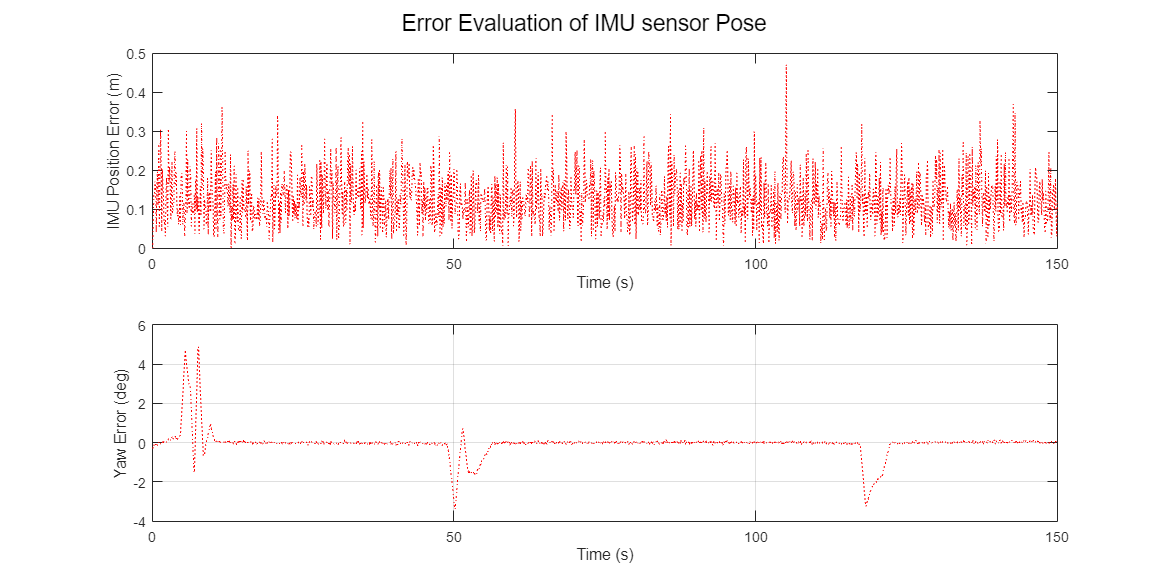

%Error in distance of IMU sensor  
YawDiffIMU = refYaw - IMUYaw;
IMUError = zeros(numFrames-1, 1);

for i= 2:numFrames-1
    IMUError(i) = sqrt((refX(i-1) - IMUX(i-1))^2 + (refY(i-1) - IMUY(i-1))^2);
end

figure;
figure('Position', [50, 50, 2000, 1000]); %[left bottom width height]

subplot(2, 1, 1);
plot(timeVector, IMUError, 'r:');
xlabel('Time (s)');
ylabel('IMU Position Error (m)');

subplot(2, 1, 2);
plot(timeVector, YawDiffIMU, 'r:');
xlabel('Time (s)');
ylabel('Yaw Error (deg)');
grid on;

sgtitle('Error Evaluation of IMU sensor Pose');

## **GPS Localization Model** 

GPSn = zeros(numFrames-1, 1);
GPSe = zeros(numFrames-1, 1);

%Reshape LLA GPS data 
GPSYaw = squeeze(Results.Course.Data(2:end));
LLA_data = squeeze(Results.LLA.Data);

%Convert course angles range from 0 to 360 to include all angles ranges
GPSPrevAngle = GPSYaw(1);

for i = 1:numFrames-1
    %Convert LLA coordinates to ENU coordinates
    [deltaE, deltaN, ~] = lla_to_enu(LLA_data(2, 1), LLA_data(1, 1), LLA_data(3, 1), LLA_data(2, i), LLA_data(1, i), LLA_data(3, i));
    GPSe(i) = deltaE;
    GPSn(i) = deltaN;

    CurrAngle = GPSYaw(i);
    if (GPSPrevAngle < 25 && GPSCurrAngle > 335)
        GPSYaw(i) = 0 - (360 - GPSYaw(i));
    elseif (GPSPrevAngle >335 && GPSCurrAngle < 25)
        GPSYaw(i) = 360 + GPSYaw(i);
    end
    GPSPrevAngle = GPSYaw(i);
end

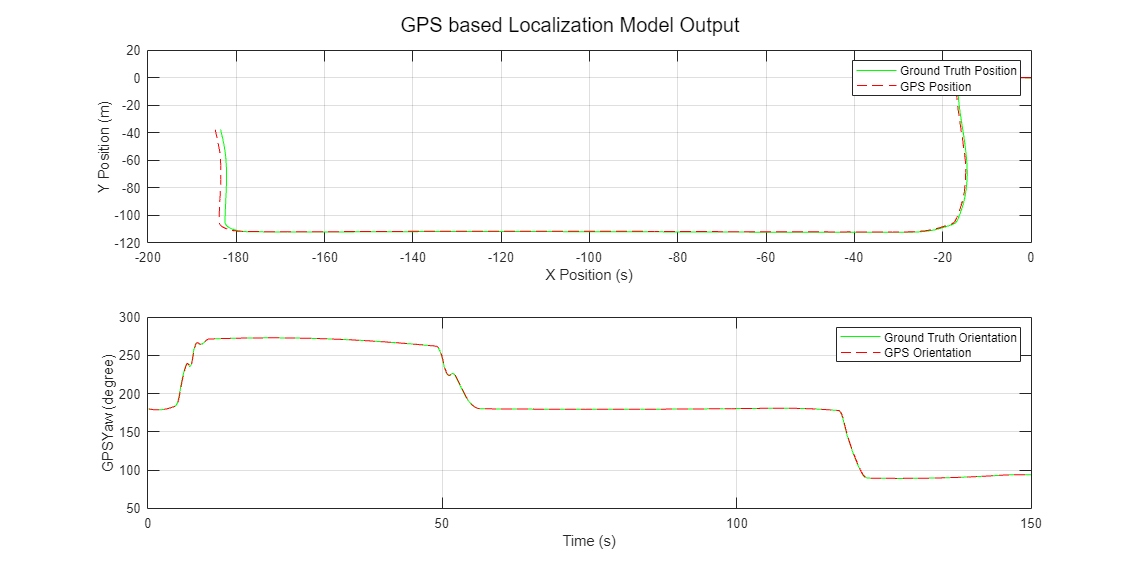

%Plot Ground Truth Pose vs. GPS Estimated Pose
figure;
figure('Position', [50, 50, 2000, 1000]); %[left bottom width height]

subplot(2, 1, 1);
plot(refX, refY, 'g');
hold on;
plot(GPSe, GPSn, 'r--');
xlabel('X Position (s)');
ylabel('Y Position (m)');
legend('Ground Truth Position', 'GPS Position');
grid on;

subplot(2, 1, 2);
plot(timeVector, refYaw, 'g');
hold on;
plot(timeVector, GPSYaw, 'r--');
xlabel('Time (s)');
ylabel('GPSYaw (degree)');
legend('Ground Truth Orientation', 'GPS Orientation');
grid on;
sgtitle('GPS based Localization Model Output');

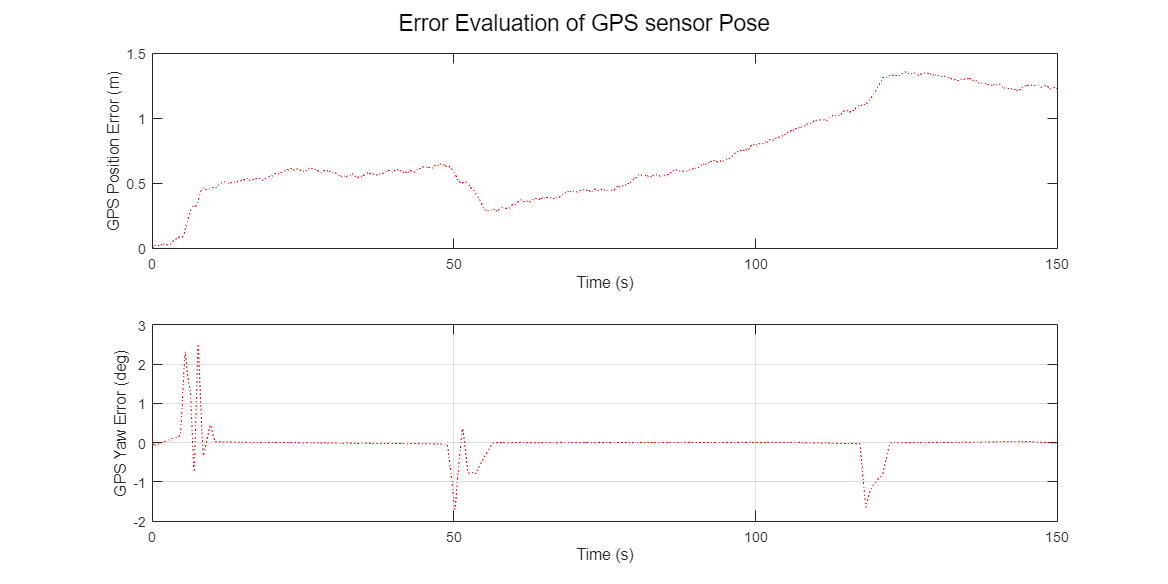

%Error in distance of GPS sensor  
YawDiffGPS = refYaw - GPSYaw;
GPSError = zeros(numFrames-1, 1);

for i= 2:numFrames-1
    GPSError(i) = sqrt((refX(i-1) - GPSe(i-1))^2 + (refY(i-1) - GPSn(i-1))^2);
end

%Graphing error
figure;
figure('Position', [50, 50, 2000, 1000]); %[left bottom width height]

subplot(2, 1, 1);
plot(timeVector, GPSError, 'r:');
xlabel('Time (s)');
ylabel('GPS Position Error (m)');

subplot(2, 1, 2);
plot(timeVector, YawDiffGPS, 'r:');
xlabel('Time (s)');
ylabel('GPS Yaw Error (deg)');
grid on;

sgtitle('Error Evaluation of GPS sensor Pose');

## **Mono-Camera Model Setup**

*This section for setting the camera Position Scale Factor and Camera Parameters Intrinsics.*

*Afterthat The Localization will done on the Mono-camera using SIFT & KAZE Functions and Essential & Fundamentals Matrices for Position and Orientation Estimation. *

*In Case you want to apply the model on another simulation and you faced an error (There is not enough features), change the no. of features from the Numeric Spinner in detection and matching features. As the number features differes from simulation to another according to the smoothiness of the images and its features, also differes according to the camera position if it's for front or rear of the vehicle or for the vehicle sides. *

%Camera Scale Factor Calculations from IMU Velocities 
IMUVx = squeeze(Results.IMUVx.Data(2:end));
IMUVy = squeeze(Results.IMUVy.Data(2:end));

Vabs = (sqrt(IMUVx.^2 + IMUVy.^2)); %Absolute Velocity 
SF = Vabs/frameRate; %Scale Factor

%Creating cameraParams intrinsics
focalLength = [fx fy];
principalPoint = [cx cy];
cameraParams = cameraIntrinsics(focalLength, principalPoint, imageSize);

### **Front Camera Localizarion Model (On the Roof of the Vehicle)**

%Store Front Camera frames in a vector
jpgFilesF = dir(fullfile('MonoCameraGray/', '*.jpg')); %Name of the folder is same as name of the created folder in ConvertVideoToFrames Function
grayVectorF = cell(1, numel(jpgFilesF));

%Store Front Camera Gray images in a vector
for i = 1:numel(jpgFilesF)
    %Construct the file path
    filePathF = fullfile('MonoCameraGray/', jpgFilesF(i).name); %Name of the folder is same as name of the created folder in ConvertVideoToFrames Function
    %Read and store the images
    grayVectorF{i} = imread(filePathF);
end

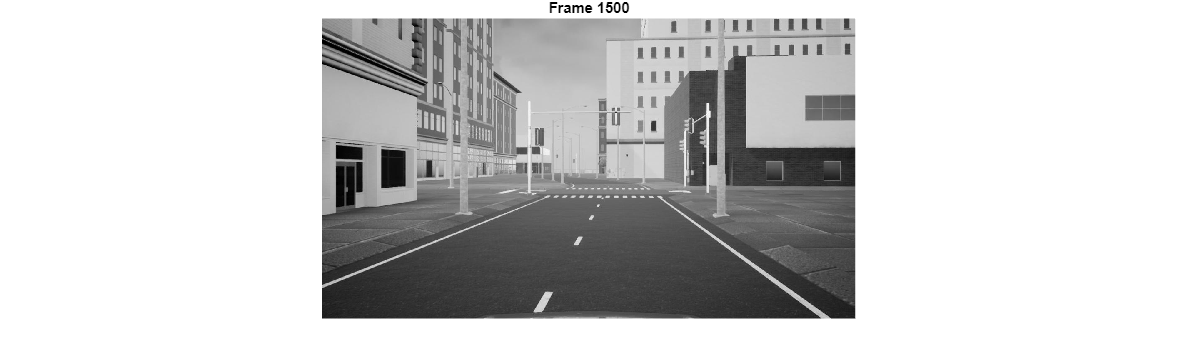

%Display the sequence of Front Camera Gray images
for i = 1:numel(grayVectorF)
    %Display the current image
    imshow(grayVectorF{i});
    title(['Frame ', num2str(i)]); %Adding frame number as a title
    pause(0.1); %Pausing the video according to recorded frame rate 
end

%Loop for saving Front Camera estimated Pose
camXF = zeros(numel(jpgFilesF),1);
camYF = zeros(numel(jpgFilesF),1);
camYawF = zeros(numel(jpgFilesF),1);
camYawF(1) = deg2rad(IMUYaw(1));

figure;
for i = 1:numel(jpgFilesF) - 1

    grayFrame1F = grayVectorF{i};
    grayFrame2F = grayVectorF{i+1};

    %Detect and match features for Position using SURF Function 
    points1FEss = detectKAZEFeatures(grayFrame1F);
    points2FEss = detectKAZEFeatures(grayFrame2F);

    [features1FEss, points1FEss] = extractFeatures(grayFrame1F, points1FEss);
    [features2FEss, points2FEss] = extractFeatures(grayFrame2F, points2FEss);
    
    indexPairsFEss = matchFeatures(features1FEss, features2FEss);

    matchedPoints1FEss = points1FEss(indexPairsFEss(:, 1), :);
    matchedPoints2FEss = points2FEss(indexPairsFEss(:, 2), :);

    %Estimate Essential matrix for Position (X & Y)
    [eMatrixF, inliersF] = estimateEssentialMatrix(matchedPoints1FEss.Location, matchedPoints2FEss.Location, cameraParams);
    
    %Select Position (X & Y) inlier points
    inlierPoints1FEss = matchedPoints1FEss(inliersF);
    inlierPoints2FEss = matchedPoints2FEss(inliersF);


    %Estimate relative camera position
    relPoseFEss = estrelpose(eMatrixF, cameraParams, inlierPoints1FEss.Location, inlierPoints2FEss.Location);
    tFEss = relPoseFEss.Translation;

    %Detect and match features for Orientation using SIFT Function
    points1FFund = detectSIFTFeatures(grayFrame1F);
    points2FFund = detectSIFTFeatures(grayFrame2F);

    [features1FFund, points1FFund] = extractFeatures(grayFrame1F, points1FFund);
    [features2FFund, points2FFund] = extractFeatures(grayFrame2F, points2FFund);
    
    indexPairsFFund = matchFeatures(features1FFund, features2FFund);
    
    matchedPoints1FFund = points1FFund(indexPairsFFund(:, 1), :);
    matchedPoints2FFund = points2FFund(indexPairsFFund(:, 2), :);

    %Estimate Fundemental matrix for Orientation (Yaw)
    [FF,inliersIndexF] = estimateFundamentalMatrix(matchedPoints1FFund.Location, matchedPoints2FFund.Location);

    inlierPoints1FFund = matchedPoints1FFund(inliersIndexF);
    inlierPoints2FFund = matchedPoints2FFund(inliersIndexF);

    %Estimate relative camera Orientation
    relPoseFFund = estrelpose(FF, cameraParams, inlierPoints1FFund.Location, inlierPoints2FFund.Location);
    RotFFund = relPoseFFund.R;

    eulerAngles = rotm2eul(RotFFund, 'XYZ');
    camYawF(i+1) = camYawF(i) - eulerAngles(2);
    camXF(i+1) = camXF(i) + tFEss(3)*cos(deg2rad(IMUYaw(i)))*SF(i) - tFEss(1)*cos((pi/2) - (deg2rad(IMUYaw(i))))*SF(i);
    camYF(i+1) = camYF(i) + tFEss(3)*sin(deg2rad(IMUYaw(i)))*SF(i) - tFEss(1)*sin(pi/2 - (deg2rad(IMUYaw(i))))*SF(i);

    %Visualization of the matched Features
    if(i==1)
        fprintf('Out of 1500 Front Camera Frames, Processing the matching Frame No.: ');
    end 
    fprintf('\b\b\b\b\b%d', i);
    %To show the matched Features uncomment the next line
    %showMatchedFeatures(grayFrame1F, grayFrame2F, inlierPoints1FEss, inlierPoints2FEss, 'montage'); 
end

Out of 1500 Front Camera Frames, Processing the matching Frame No.: 

1499

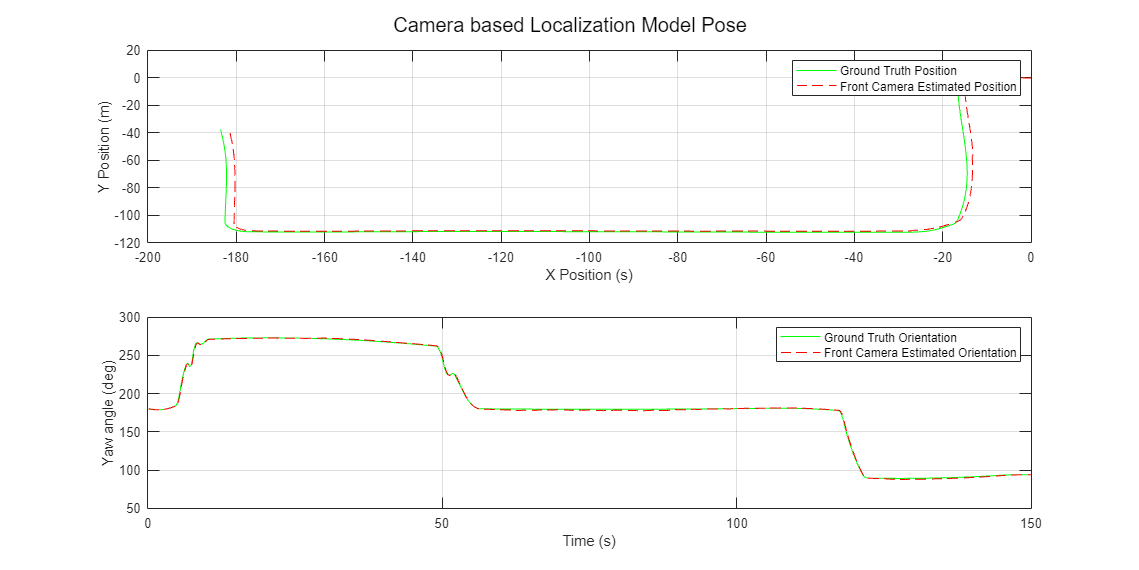

%camYawF = rad2deg(camYawF); %Run it only once
%Plot Ground Truth Pose vs. Front camera Estimated Pose
figure;
figure('Position', [50, 50, 2000, 1000]); %[left bottom width height]

subplot(2, 1, 1);
plot(refX, refY, 'g');
hold on;
plot(camXF, camYF, 'r--');
xlabel('X Position (s)');
ylabel('Y Position (m)');
legend('Ground Truth Position', 'Front Camera Estimated Position');
grid on;

subplot(2, 1, 2);
plot(timeVector, refYaw, 'g');
hold on;
plot(timeVector, camYawF, 'r--');
xlabel('Time (s)');
ylabel('Yaw angle (deg)');
legend('Ground Truth Orientation', 'Front Camera Estimated Orientation');
grid on;
sgtitle('Camera based Localization Model Pose');

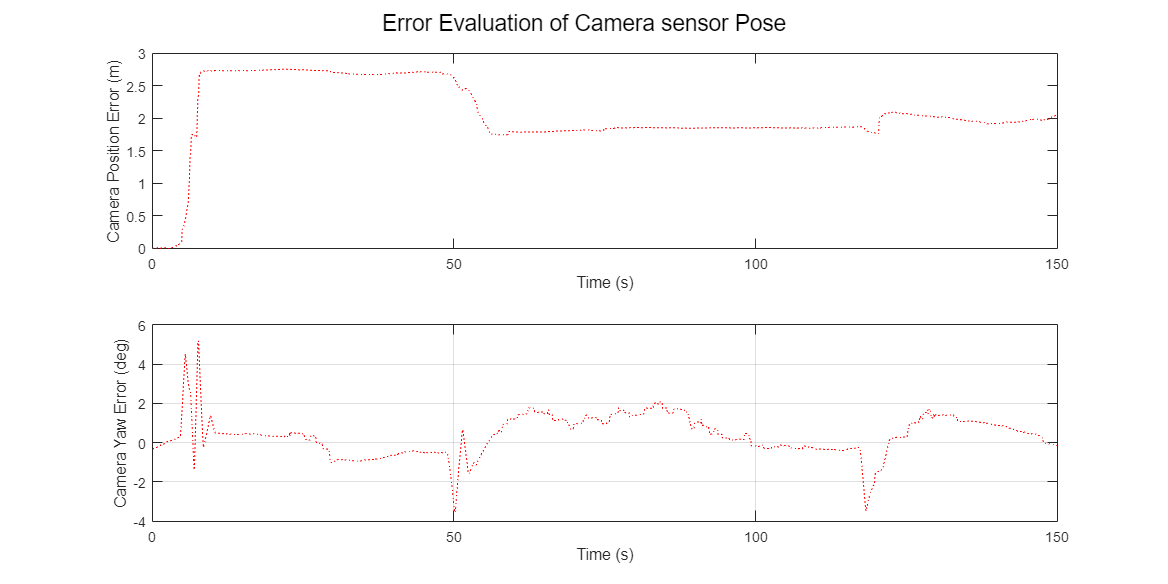

%Error in distance of Camera sensor  
YawDiffCamF = refYaw - camYawF;
CameraError = zeros(numFrames-1, 1);

for i= 2:numFrames-1
    CameraError(i) = sqrt((refX(i-1) - camXF(i-1))^2 + (refY(i-1) - camYF(i-1))^2);
end

%Graphing error
figure;
figure('Position', [50, 50, 2000, 1000]); %[left bottom width height]

subplot(2, 1, 1);
plot(timeVector, CameraError, 'r:');
xlabel('Time (s)');
ylabel('Camera Position Error (m)');

subplot(2, 1, 2);
plot(timeVector, YawDiffCamF, 'r:');
xlabel('Time (s)');
ylabel('Camera Yaw Error (deg)');
grid on;

sgtitle('Error Evaluation of Camera sensor Pose');

## **Lidar Localization Model**

%Visualize point cloud data
xlimits = [-150 150];
ylimits = [-150 150];
zlimits = [ -5 10];
coder.extrinsic('isOpen', 'pcplayer')
%player = pcplayer(xlimits, ylimits, zlimits);
pcdData = Results.ptCloudData1.signals.values;
pcdArray = reshape(pcdData, [(Vfov/Vres)*(Hfov/Hres), 3, size(pcdData,4)]);

for i = 2:size(pcdData,4)
    pcdX = pcdArray(:, 1,i);
    pcdY = pcdArray(:, 2,i);
    pcdZ = pcdArray(:, 3,i);
    point_cloud_data = [pcdX, pcdY, pcdZ];
    
    % Update the plot with the point cloud for the current frame
    %view(player, point_cloud_data)
    %pause(0.1); % Adjust the pause duration as needed
end

pointCloudObjects = cell(numFrames);
for i = 1:numFrames-1
 % Convert the array to a pointCloud object
 pointCloudObjects{i} = pointCloud(pcdArray(:,:,i));
 pointCloudObjects{i} = pcdownsample(pointCloudObjects{i}, 'gridAverage', 0.5);
end

LidarX = zeros(1, numFrames-1);
LidarY = zeros(1, numFrames-1);
LidarYaw = zeros(1, numFrames-1);
LidarXBar = zeros(1, numFrames-1);
LidarYBar = zeros(1, numFrames-1);

for i = 2:numFrames-1
    ptCloudOne = pointCloudObjects{i-1};
    ptCloudTwo = pointCloudObjects{i};
    [tform, ~, ~] = pcregistericp(ptCloudOne, ptCloudTwo, Metric="pointToPlane");
    
    % Extract rotation matrix and translation vector from transformation matrix
    R = tform.T(1:3, 1:3);
    eulerAngles = rotm2eul(R, 'XYZ');
    deltaYaw_vehicle_deg = double(rad2deg(eulerAngles(3)));
    t = tform.T(4, 1:3)';
    
    deltaY_vehicle_m = - (t(1) * sin(deg2rad(LidarYaw(i-1)+IMUYaw(1)))) + (t(2) * cos(deg2rad(LidarYaw(i-1)+IMUYaw(1)))); %Referencing to US city block Map coordinates
    deltaX_vehicle_m = (t(2) * sin(deg2rad(LidarYaw(i-1)+IMUYaw(1)))) - (t(1) * cos(deg2rad(LidarYaw(i-1)+IMUYaw(1))));
    deltaYBar_vehicle_m = - (t(1) * sin(deg2rad(IMUYaw(i-1)))) + (t(2) * cos(deg2rad(IMUYaw(i-1)))); %Referencing to US city block Map coordinates
    deltaXBar_vehicle_m = (t(2) * sin(deg2rad(IMUYaw(i-1)))) - (t(1) * cos(deg2rad(IMUYaw(i-1))));
    LidarX(i) = LidarX(i-1) + deltaX_vehicle_m;
    LidarY(i) = LidarY(i-1) + deltaY_vehicle_m;
    LidarXBar(i) = LidarXBar(i-1) + deltaXBar_vehicle_m;
    LidarYBar(i) = LidarYBar(i-1) + deltaYBar_vehicle_m;
    LidarYaw(i) = LidarYaw(i-1) + deltaYaw_vehicle_deg;    
    
    %Display No. of Iterations
    if(i==2)
        fprintf('Out of 1500 Frames, Processing the matching Point Cloud No.: ');
    end 
    fprintf('\b\b\b\b\b%d', i);
end

Out of 1500 Frames, Processing the matching Point Cloud No.: 

1500

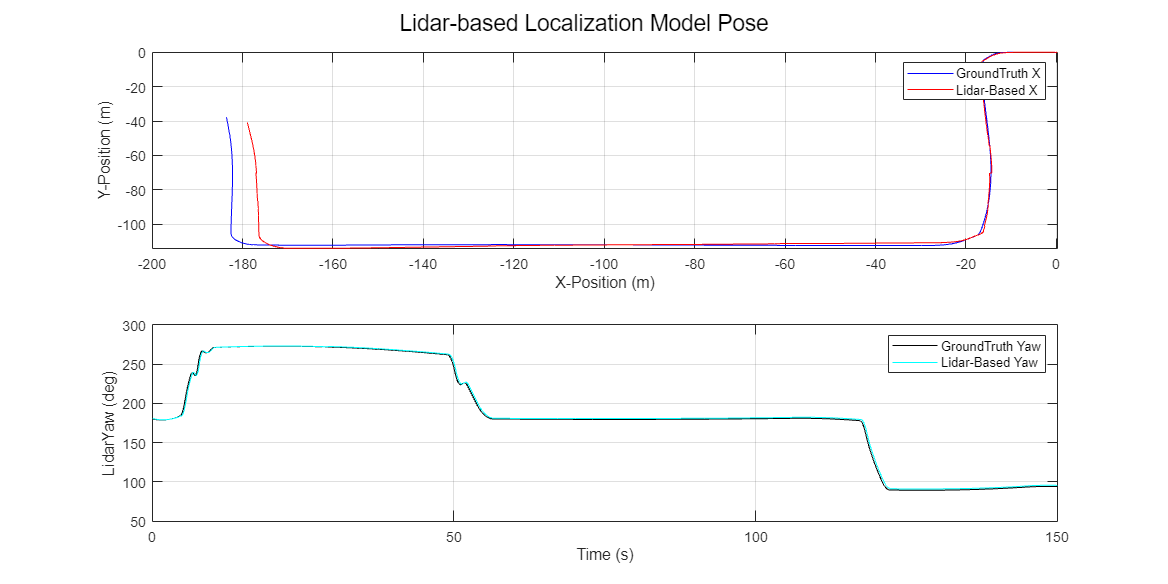

%Plot Ground Truth Pose vs. Lidar Estimated Pose
figure;
figure('Position', [50, 50, 2000, 1000]); %[left bottom width height]

%Plot Position X & Y
subplot(2, 1, 1);
plot(refX, refY, 'b', LidarX, LidarY, 'r');
xlabel('X-Position (m)');
ylabel('Y-Position (m)');
legend('GroundTruth X', 'Lidar-Based X');
grid on;

%Plot Orientation Yaw
subplot(2, 1, 2);
plot(timeVector, refYaw, 'k', timeVector, LidarYaw+IMUYaw(1), 'c');
xlabel('Time (s)');     
ylabel('LidarYaw (deg)');
legend('GroundTruth Yaw', 'Lidar-Based Yaw');
grid on;
sgtitle('Lidar-based Localization Model Pose');

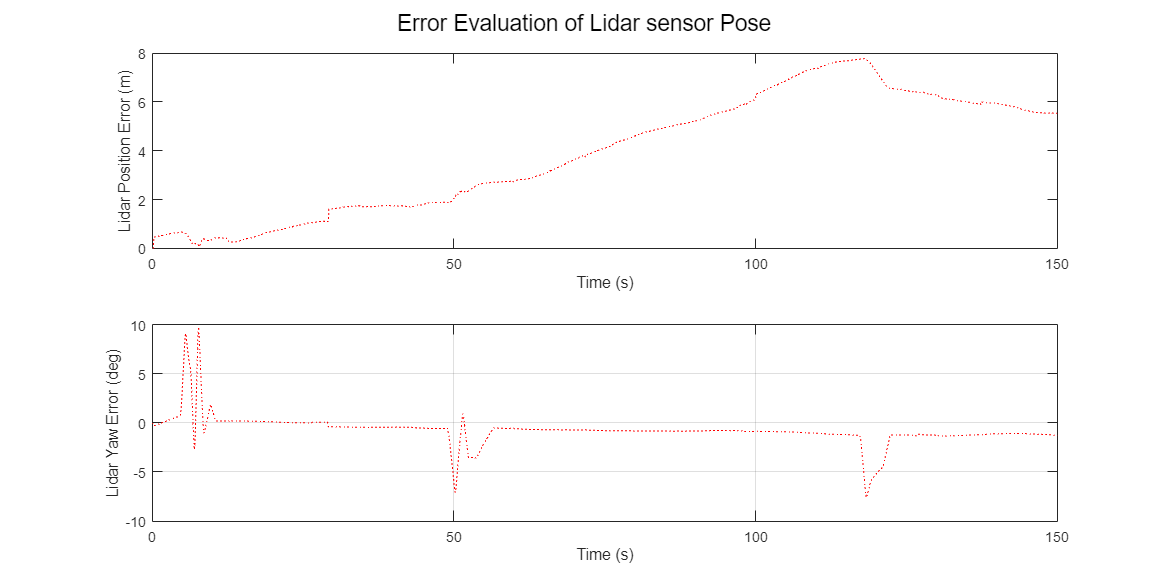

%Error in distance of Camera sensor  
LidardiffYaw = refYaw - (LidarYaw+refYaw(1))';
LidarError = zeros(numFrames-1, 1);

for i= 2:numFrames-1
    LidarError(i) = sqrt((refX(i-1) - LidarX(i-1)')^2 + (refY(i-1) - LidarY(i-1)')^2);
end

%Graphing error
figure;
figure('Position', [50, 50, 2000, 1000]); %[left bottom width height]

subplot(2, 1, 1);
plot(timeVector, LidarError, 'r:');
xlabel('Time (s)');
ylabel('Lidar Position Error (m)');

subplot(2, 1, 2);
plot(timeVector, LidardiffYaw, 'r:');
xlabel('Time (s)');
ylabel('Lidar Yaw Error (deg)');
grid on;

sgtitle('Error Evaluation of Lidar sensor Pose');

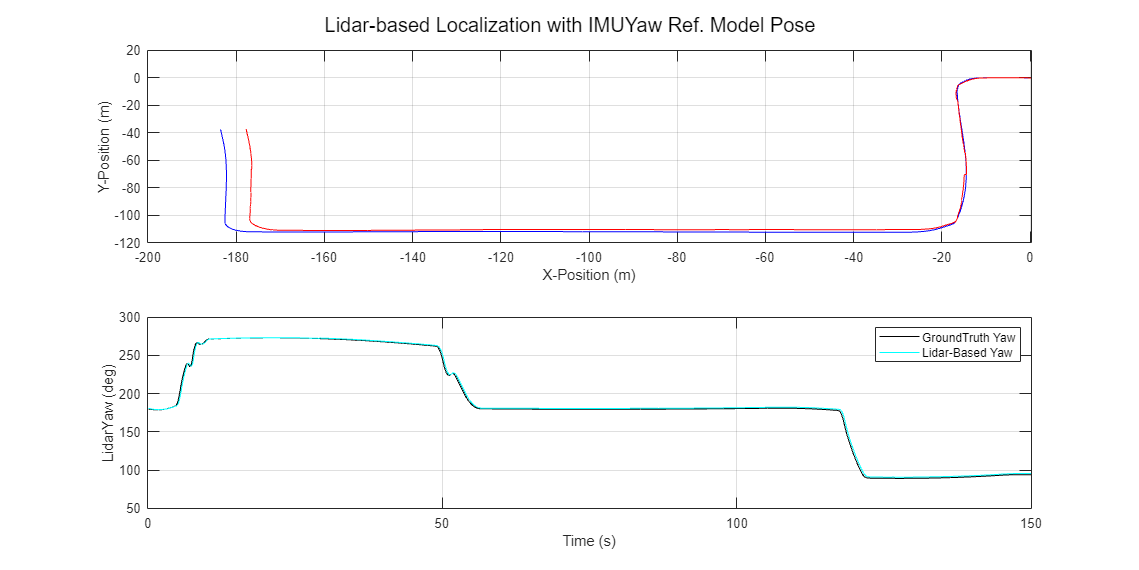

%Plot Ground Truth Pose vs. Lidar Estimated Pose with IMUYaw Ref.
figure;
figure('Position', [50, 50, 2000, 1000]); %[left bottom width height]

%Plot Position X & Y
subplot(2, 1, 1);
plot(refX, refY, 'b', LidarXBar, LidarYBar, 'r');
xlabel('X-Position (m)');
ylabel('Y-Position (m)');
%legend('GroundTruth X', 'Lidar-Based X');
grid on;

%Plot Orientation Yaw
subplot(2, 1, 2);
plot(timeVector, refYaw, 'k', timeVector, (LidarYaw+IMUYaw(1)), 'c');
xlabel('Time (s)');     
ylabel('LidarYaw (deg)');
legend('GroundTruth Yaw', 'Lidar-Based Yaw');
grid on;
sgtitle('Lidar-based Localization with IMUYaw Ref. Model Pose');

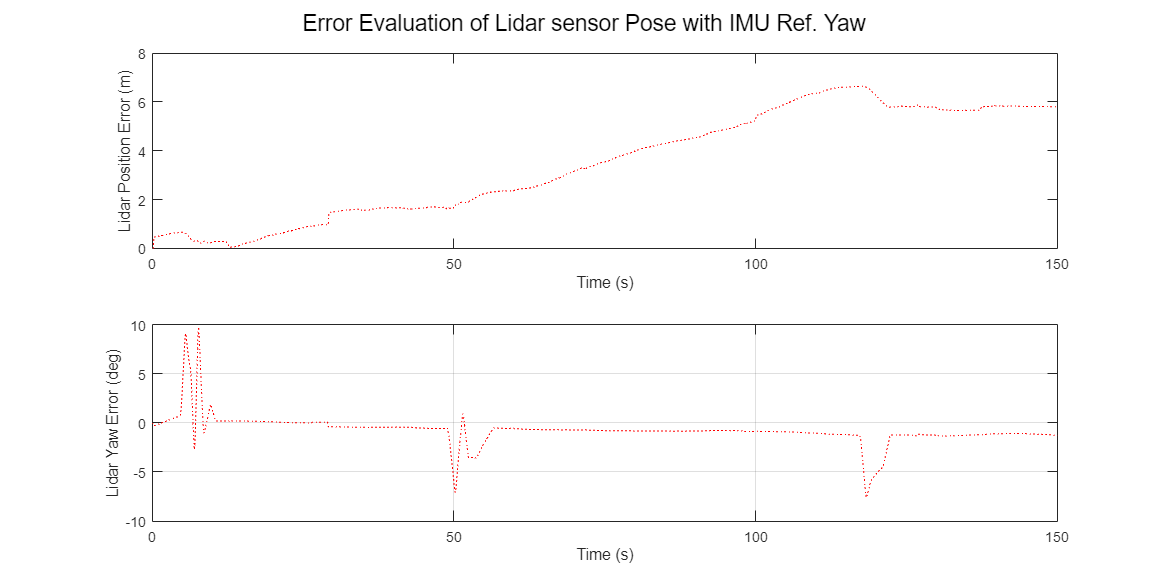

%Error in distance of Camera sensor  
LidardiffYaw = refYaw - (LidarYaw+refYaw(1))';
LidarError = zeros(numFrames-1, 1);

for i= 2:numFrames-1
    LidarError(i) = sqrt((refX(i-1) - LidarXBar(i-1)')^2 + (refY(i-1) - LidarYBar(i-1)')^2);
end

%Graphing error
figure;
figure('Position', [50, 50, 2000, 1000]); %[left bottom width height]

subplot(2, 1, 1);
plot(timeVector, LidarError, 'r:');
xlabel('Time (s)');
ylabel('Lidar Position Error (m)');

subplot(2, 1, 2);
plot(timeVector, LidardiffYaw, 'r:');
xlabel('Time (s)');
ylabel('Lidar Yaw Error (deg)');
grid on;

sgtitle('Error Evaluation of Lidar sensor Pose with IMU Ref. Yaw');

## **Sensory Data Fusion**

### Standard Kalman Filter

%Now with all data stored and set to be used in evaluating different filters estimates.
%Using Kalman Filter as follows (Initialzing Parameters and matrices (dt, F, G, H, Q, R) -> Setting Initial estimates -> Main Loop (Prediction -> update))

%1- Initialzing Parameters and Matrices 
dt = 0.1; %Time step for used synced data approximately.

%Initializing State Transition matrix (F)
F = [1, 0, dt, 0, 0;
     0, 1, 0, dt, 0;
     0, 0, 1, 0, 0;
     0, 0, 0, 1, 0;
     0, 0, 0, 0, 1];

%Initializing Control Matrix (G)
G = [(dt^2)/2, 0, 0;
     0, (dt^2)/2, 0;
     dt, 0, 0;
     0, dt, 0;
     0, 0, dt];

%Initializing Measurements matrix (H)
H = [1, 0, 0, 0, 0;
     0, 1, 0, 0, 0;
     0, 0, 0, 0, 1;
     1, 0, 0, 0, 0;
     0, 1, 0, 0, 0;
     0, 0, 0, 0, 1;
     1, 0, 0, 0, 0;
     0, 1, 0, 0, 0;
     0, 0, 0, 0, 1];

%Initializing Process noise covariance matrix (Q)
Q = diag([0.2, 0.2, 0.01, 0.01, 0.2].^2);

%Initializing Measurement noise covariance matrix (R) for every sensor
R = diag([0.392, 0.392, 0.3, 0.55, 0.55, 0.6, 0.12, 0.12, 0.12].^2); %CAMERA -> LIDAR -> GPS

%2-Setting initial estimates
%Initializing variables vector to hold xCheck, xHat, pCheck, pHat
xCheck = zeros(numFrames-1,5,1)';
pCheck = zeros(numFrames-1,5,5);
xHat = zeros(numFrames-1,5,1)'; % (+1) for inital estimates -> xHat(0)
pHat = zeros(numFrames-1,5,5); % (+1) for inital estimates -> pHat(0)
K = zeros(numFrames-1,5,9);

%Initializing state estimates xHat(k-1) -> first prediction iteration
xHat(:,1) = zeros(5,1); %[refX(0); refY(0); ve(0); vn(0); refYaw(0);]; -> are all assumed to be zero
xHat(5,1) = IMUYaw(1);

%Initializing error covariance estimates pHat(k-1) -> first prediction iteration
pHat(1,:,:) = eye(5);

%IMU X & Y directions Acceleration
dtime = diff(timeVector);
Ae = diff(IMUVx) ./ dtime; 
An = diff(IMUVy) ./ dtime; 

%Get Angular Velocity from IMUYaw
wu = diff(IMUYaw) ./ dtime; 

%Input matrix
u = [Ae An wu]';

%Measurement Matrix y
y = [camXF camYF camYawF LidarXBar' LidarYBar' (LidarYaw+IMUYaw(1))' GPSe GPSn GPSYaw]'; %to store input with size with size 9*numFrames

%3.0-Main filter loop
for i = 2:numFrames-1
    %Prediction step
    xCheck(:,i) = (F * xHat(:,i-1)) + (G * u(:,i-1)); %Replacing initial estimates with zeros to work with absolute difference readings
    pCheck(i,:,:) = (F * reshape(pHat(i-1,:,:),5, 5) * F') + Q;
    %Update step -> proceeed update step in 3 stages ->
    K(i,:,:) = (reshape(pCheck(i,:,:), 5, 5) * H') * (inv(((H *reshape(pCheck(i,:,:), 5, 5) * H') + R)));
    xHat(:,i) = xCheck(:,i) + reshape(K(i,:,:), 5, 9)*(y(:,i) - (H * xCheck(:,i)));
    pHat(i,:,:) = (eye(5) - (reshape(K(i,:,:), 5, 9) * H)) * reshape(pCheck(i,:,:),5, 5);
end

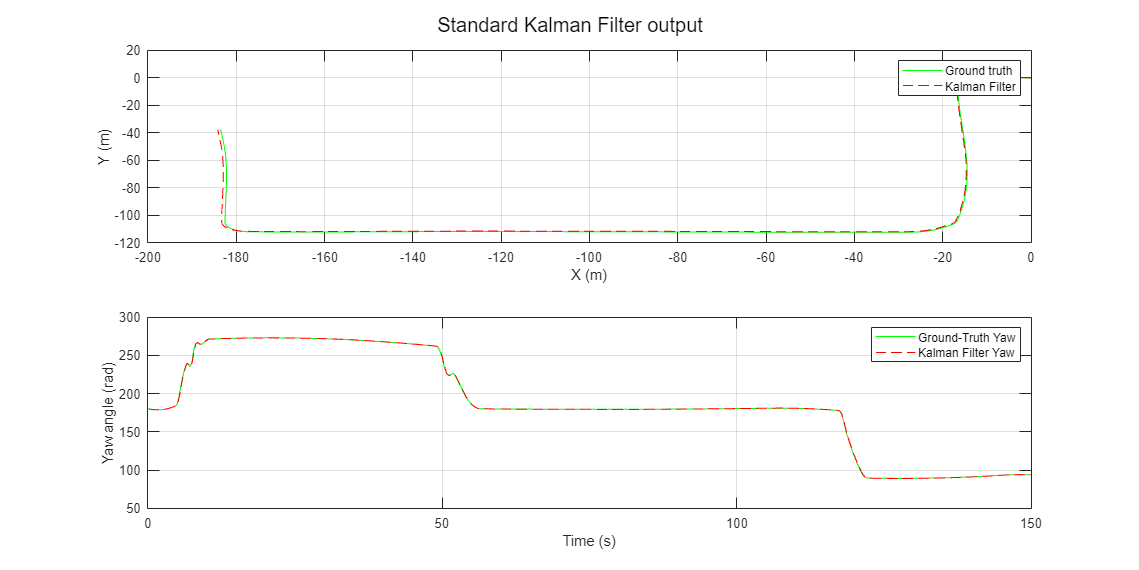

%Seperating 2D Pose from states for visualization
kfX = xHat(1, :);
kfY = xHat(2, :);
kfYaw = xHat(5, :);
%Graphing Filter output in comparison with GPS data as the ground truth
figure;
figure('Position', [50, 50, 2000, 1000]); % [left bottom width height]

subplot(2, 1, 1);
plot(refX, refY, 'g');
hold on;
plot(kfX, kfY, 'r--');
xlabel('X (m)');
ylabel('Y (m)');
legend('Ground truth', 'Kalman Filter');
grid on;

subplot(2, 1, 2);
plot(timeVector, refYaw, 'g');
hold on;
plot(timeVector, kfYaw, 'r--');
xlabel('Time (s)');
ylabel('Yaw angle (rad)');
legend('Ground-Truth Yaw', 'Kalman Filter Yaw');
grid on;
sgtitle('Standard Kalman Filter output');       

### Weighted Sum Estimation Including GPS

XGWs = zeros(numFrames-1, 1);
YGWs = zeros(numFrames-1, 1);
YawGWs = zeros(numFrames-1, 1);

XSenGWs = [camXF, LidarXBar', GPSe, IMUX];
YSenGWs = [camYF, LidarYBar', GPSn, IMUY]; 
YawSenGWs = [camYawF, (LidarYaw+IMUYaw(1))', GPSYaw, IMUYaw];

WeigthGXY = [5, 5, 20, 25]; %Camera -> Lidar -> GPS -> IMU
WeigthGYaw = [5, 8, 20, 25]; %Camera -> Lidar -> GPS -> IMU

%Loop for Weighted sum cal.
for i= 1:numFrames-1
    XGWs(i,:) = sum(WeigthGXY .* XSenGWs(i,:)) / sum(WeigthGXY);
    YGWs(i,:) = sum(WeigthGXY .* YSenGWs(i,:)) / sum(WeigthGXY);
    YawGWs(i,:) = sum(WeigthGYaw .* YawSenGWs(i,:)) / sum(WeigthGYaw);
end

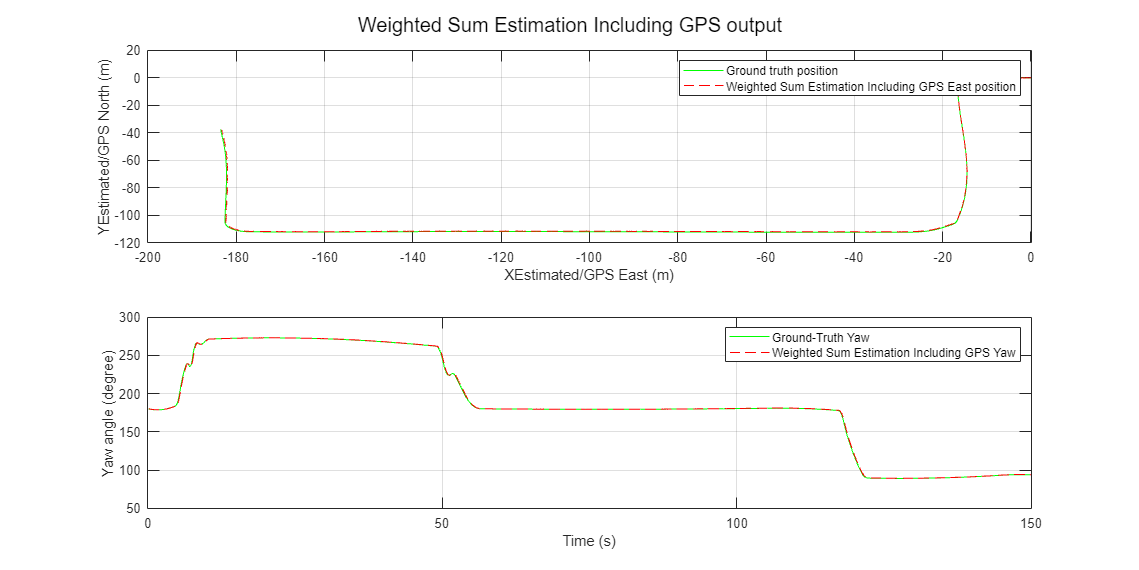

%Graphing Weighted Sum Estimation Including GPS output in comparison with GPS data as the ground truth
figure;
figure('Position', [50, 50, 2000, 1000]); %[left bottom width height]

subplot(2, 1, 1);
plot(refX, refY, 'g');
hold on;
plot(XGWs, YGWs, 'r--');
xlabel('XEstimated/GPS East (m)');
ylabel('YEstimated/GPS North (m)');
legend('Ground truth position', 'Weighted Sum Estimation Including GPS East position');
grid on;

subplot(2, 1, 2);
plot(timeVector, refYaw, 'g');
hold on;
plot(timeVector, YawGWs, 'r--');
xlabel('Time (s)');
ylabel('Yaw angle (degree)');
legend('Ground-Truth Yaw', 'Weighted Sum Estimation Including GPS Yaw');
grid on;
sgtitle('Weighted Sum Estimation Including GPS output');

### Weighted Sum Estimation Excluding GPS

XWs = zeros(numFrames-1, 1);
YWs = zeros(numFrames-1, 1);
YawWs = zeros(numFrames-1, 1);

WeigthXY = [6, 4, 0, 30];
WeigthYaw = [6, 3, 0, 10];

%Loop for Weighted sum cal.
for i= 1:numFrames-1
    XWs(i,:) = sum(WeigthXY .* XSenGWs(i,:)) / sum(WeigthXY);
    YWs(i,:) = sum(WeigthXY .* YSenGWs(i,:)) / sum(WeigthXY);
    YawWs(i,:) = sum(WeigthYaw .* YawSenGWs(i,:)) / sum(WeigthYaw);
end

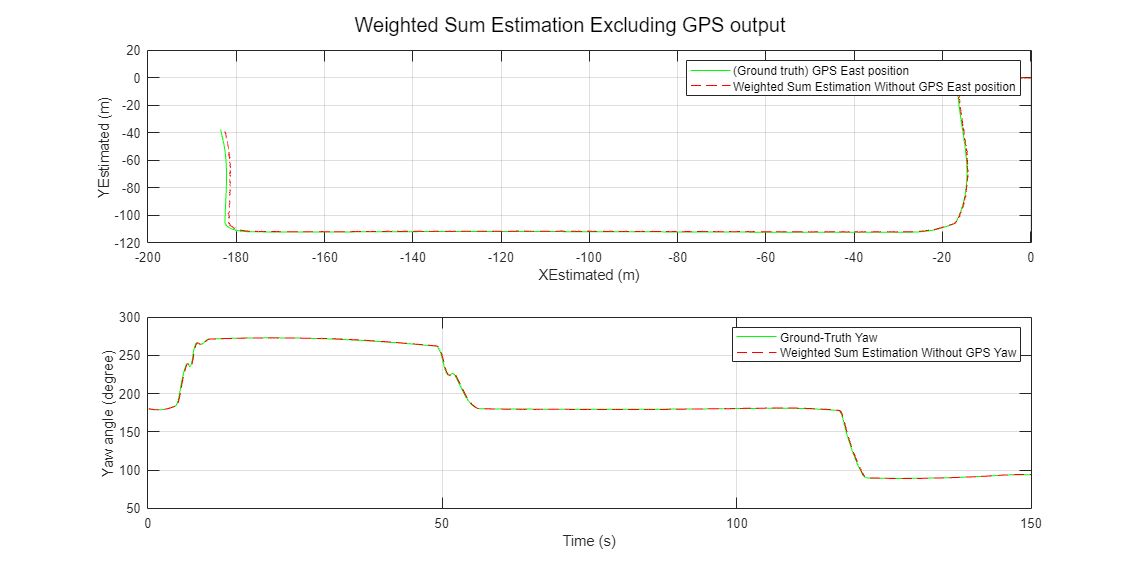

%Graphing Average Estimation output in comparison with GPS data as the ground truth
figure;
figure('Position', [50, 50, 2000, 1000]); %[left bottom width height]

subplot(2, 1, 1);
plot(refX, refY, 'g');
hold on;
plot(XWs, YWs, 'r--');
xlabel('XEstimated (m)');
ylabel('YEstimated (m)');
legend('(Ground truth) GPS East position', 'Weighted Sum Estimation Without GPS East position');
grid on;

subplot(2, 1, 2);
plot(timeVector, refYaw, 'g');
hold on;
plot(timeVector, YawWs, 'r--');
xlabel('Time (s)');
ylabel('Yaw angle (degree)');
legend('Ground-Truth Yaw', 'Weighted Sum Estimation Without GPS Yaw');
grid on;
sgtitle('Weighted Sum Estimation Excluding GPS output');

### **Average Estimation Model**

XAvg = zeros(numFrames-1, 1);
YAvg = zeros(numFrames-1, 1);
YawAvg = zeros(numFrames-1, 1);

for i= 1:numFrames-1
    XAvg(i) = (camXF(i,:) + LidarXBar(:,i) + GPSe(i,:) + IMUX(i,:)) / 4;
    YAvg(i) = (camYF(i,:) + LidarYBar(:,i) + GPSn(i,:) + IMUY(i,:)) / 4;
    YawAvg(i) = (camYawF(i,:) + (LidarYaw(:,i)+refYaw(1)) + GPSYaw(i,:) + IMUYaw(i,:)) / 4;
end

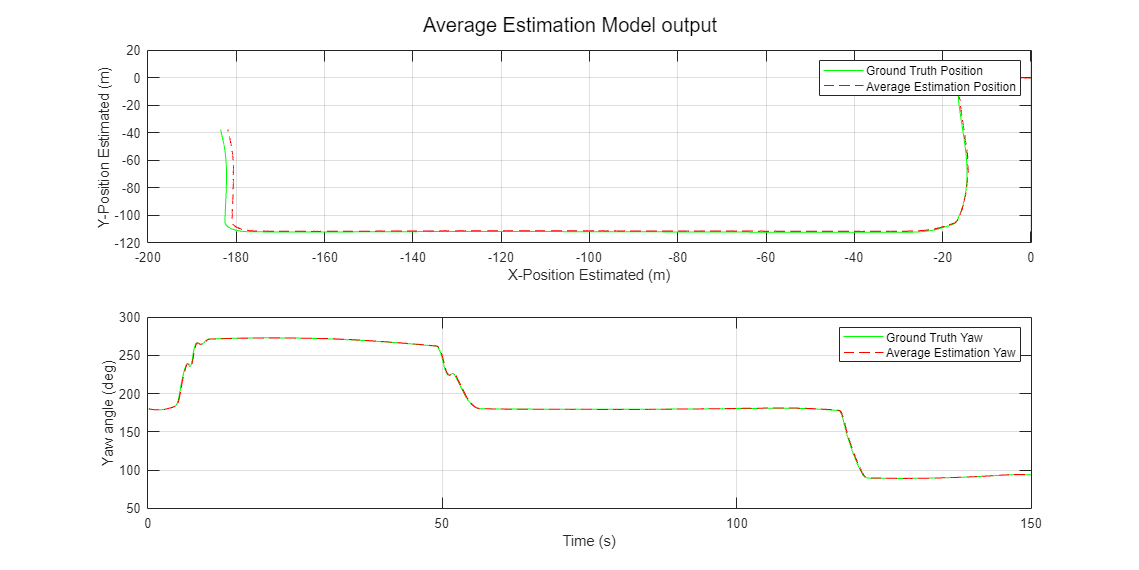

%Graphing Average Estimation output in comparison with GPS data as the ground truth
figure;
figure('Position', [50, 50, 2000, 1000]); %[left bottom width height]

subplot(2, 1, 1);
plot(refX, refY, 'g');
hold on;
plot(XAvg, YAvg, 'r--');
xlabel('X-Position Estimated (m)');
ylabel('Y-Position Estimated (m)');
legend('Ground Truth Position', 'Average Estimation Position');
grid on;

subplot(2, 1, 2);
plot(timeVector, refYaw, 'g');
hold on;
plot(timeVector, YawAvg, 'r--');
xlabel('Time (s)');
ylabel('Yaw angle (deg)');
legend('Ground Truth Yaw', 'Average Estimation Yaw');
grid on;
sgtitle('Average Estimation Model output');

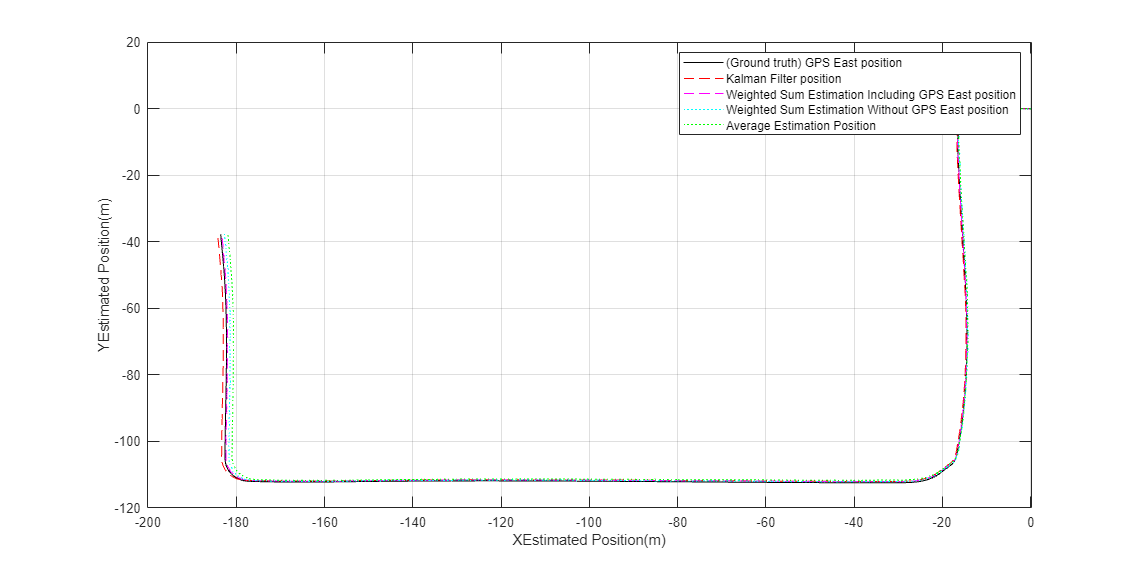

%Graph all Sensors Route 
figure;
figure('Position', [50, 50, 2000, 1000]); % [left bottom width height]

plot(refX, refY, 'black-');
hold on;
plot(kfX, kfY, 'r--');
plot(XGWs, YGWs, 'm--');
plot(XWs, YWs, 'c:');
plot(XAvg, YAvg, 'g:');
xlabel('XEstimated Position(m)');
ylabel('YEstimated Position(m)');
legend('(Ground truth) GPS East position', 'Kalman Filter position', 'Weighted Sum Estimation Including GPS East position', 'Weighted Sum Estimation Without GPS East position', 'Average Estimation Position');
grid on;

%To obtain total distance of travel 
totalDist = 0;
dkf = zeros(numFrames-1, 1);
dGWs = zeros(numFrames-1, 1);
dWs = zeros(numFrames-1, 1);
dAvg = zeros(numFrames-1, 1);
for i= 2:numFrames-1
    deltaX = refX(i) - refX(i-1);
    deltaY = refY(i) - refY(i-1);
    dist = sqrt(deltaX^2 + deltaY^2);
    totalDist = totalDist + dist;
end
for i= 1:numFrames-1
    dkf(i)= sqrt((refX(i) - kfX(i))^2 + (refY(i) - kfY(i))^2);
    dGWs(i) = sqrt((refX(i) - XGWs(i))^2 + (refY(i) - YGWs(i))^2);
    dWs(i) = sqrt((refX(i) - XWs(i))^2 + (refY(i) - YWs(i))^2);
    dAvg(i) = sqrt(((refX(i) - XAvg(i))^2 + (refY(i) - YAvg(i))^2));
end

%Displaying Average accuracy score per path
fprintf(['For a route with length = %f m\n________________________________________\n\n' ...
    'Average Estimates Max Deviation = %f m\n\nWeighted Estimates Excluding GPS Max Deviation = %f m\n\n' ...
    'Weighted Estimates Max Deviation = %f m\n\n' ...
    'KF Estimates Max Deviation = %f m\n'], totalDist, max(dAvg), max(dWs), max(dGWs), max(dkf));  

For a route with length = 359.407835 m
________________________________________

Average Estimates Max Deviation = 1.930291 m

Weighted Estimates Excluding GPS Max Deviation = 1.186226 m

Weighted Estimates Max Deviation = 0.676610 m

KF Estimates Max Deviation = 0.783626 m


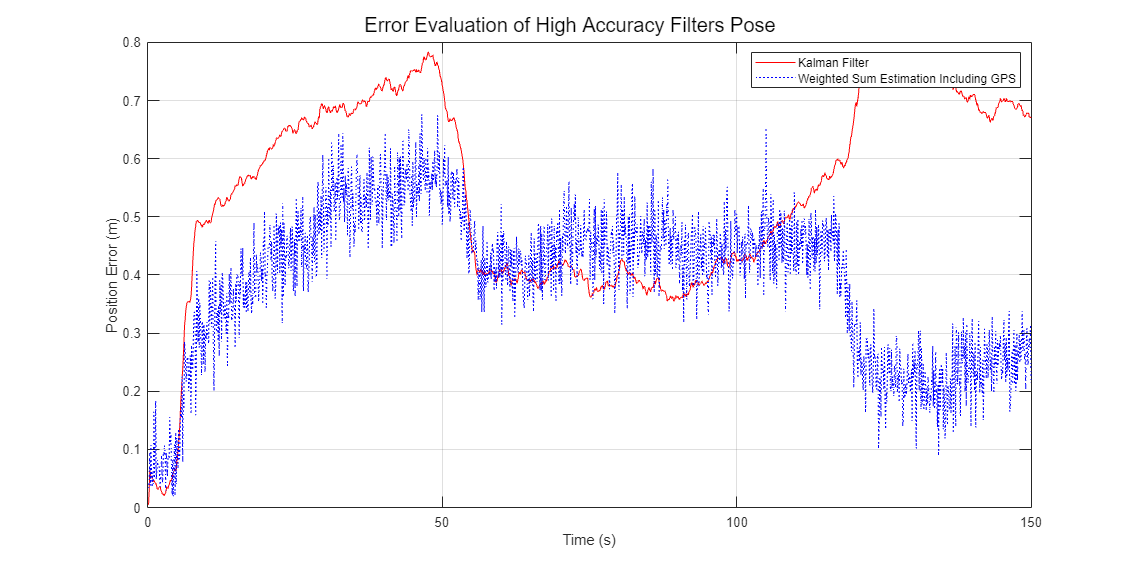

%Error Evaluation of Sensor Fusion Filters Pose
figure;
figure('Position', [50, 50, 2000, 1000]); %[left bottom width height]

plot(timeVector, dkf, '-r');
hold on;
plot(timeVector, dGWs, 'b:');
xlabel('Time (s)');
ylabel('Position Error (m)');
legend('Kalman Filter', 'Weighted Sum Estimation Including GPS');
grid on;

sgtitle('Error Evaluation of High Accuracy Filters Pose');

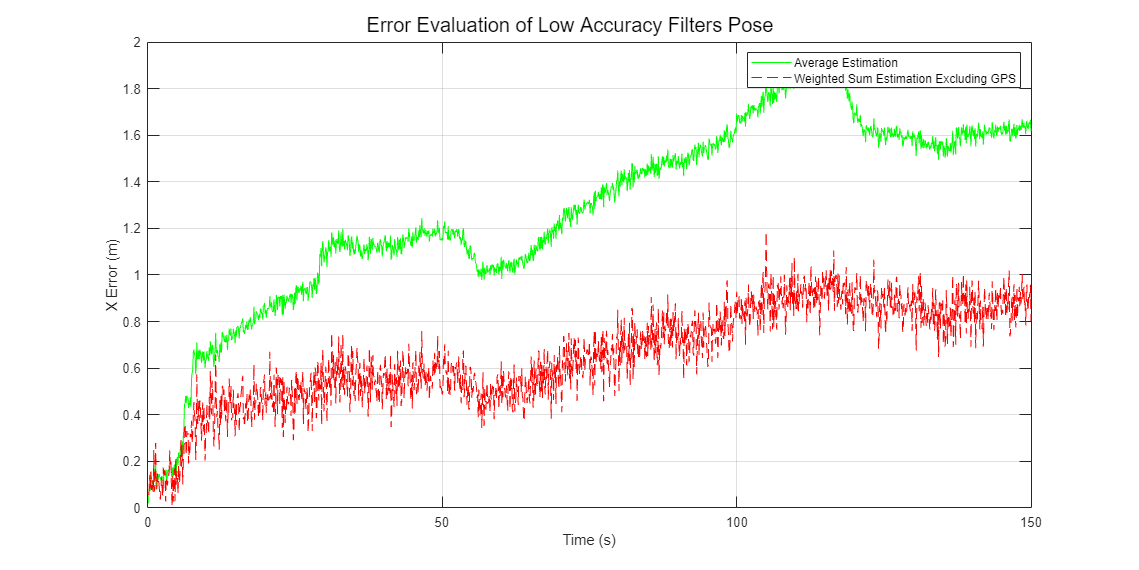

%Error Evaluation of Sensor Fusion Filters Pose
figure;
figure('Position', [50, 50, 2000, 1000]); %[left bottom width height]

plot(timeVector, dAvg, 'g');
hold on;
plot(timeVector, dWs, 'r--');

xlabel('Time (s)');
ylabel('X Error (m)');
legend('Average Estimation', 'Weighted Sum Estimation Excluding GPS');
grid on;

sgtitle('Error Evaluation of Low Accuracy Filters Pose');

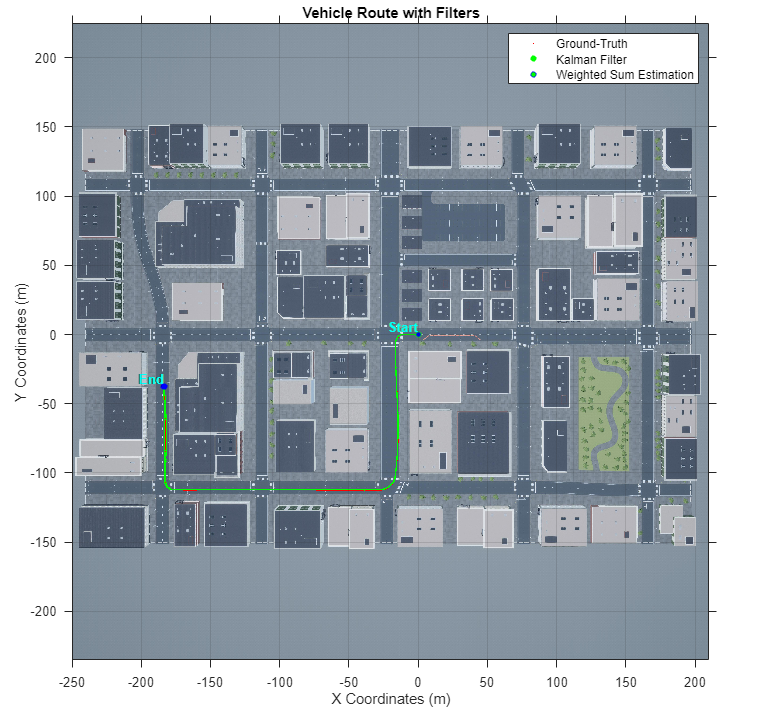

%Visualize the Position on US City Block Map
data = load('sim3d_SpatialReferences.mat');
spatialRef = data.spatialReference.USCityBlock;

figure;
fileName = 'sim3d_USCityBlock.jpg';
imshow(fileName,spatialRef);
set(gca,'YDir','normal')
xlabel('X Coordinates (m)')
ylabel('Y Coordinates (m)')

%Plot the position data
hold on;
plot(refX, refY, 'ro', 'MarkerSize', 0.5, 'MarkerFaceColor', 'r');
plot(refX(1), refY(1), 'go', 'MarkerSize', 4, 'MarkerFaceColor', 'g'); % Start point
text(refX(1), refY(1), 'Start', 'VerticalAlignment', 'bottom', 'HorizontalAlignment', 'right', 'FontSize', 10, 'FontWeight', 'bold', 'Color', 'y');
plot(refX(end), refY(end), 'bo', 'MarkerSize', 4, 'MarkerFaceColor', 'g'); % End point
text(refX(end), refY(end), 'End', 'VerticalAlignment', 'bottom', 'HorizontalAlignment', 'right', 'FontSize', 10, 'FontWeight', 'bold', 'Color', 'y');
hold on;
plot(kfX, kfY, 'go', 'MarkerSize', 0.5, 'MarkerFaceColor', 'black');
plot(kfX(1), kfY(1), 'go', 'MarkerSize', 4, 'MarkerFaceColor', 'black'); % Start point
text(kfX(1), kfY(1), 'Start', 'VerticalAlignment', 'bottom', 'HorizontalAlignment', 'right', 'FontSize', 10, 'FontWeight', 'bold', 'Color', 'black');
plot(kfX(end), kfY(end), 'bo', 'MarkerSize', 4, 'MarkerFaceColor', 'black'); % End point
text(kfX(end), kfY(end), 'End', 'VerticalAlignment', 'bottom', 'HorizontalAlignment', 'right', 'FontSize', 10, 'FontWeight', 'bold', 'Color', 'black');
plot(XGWs, YGWs, 'go', 'MarkerSize', 0.5, 'MarkerFaceColor', 'm');
plot(XGWs(1), YGWs(1), 'go', 'MarkerSize', 4, 'MarkerFaceColor', 'b'); % Start point
text(XGWs(1), YGWs(1), 'Start', 'VerticalAlignment', 'bottom', 'HorizontalAlignment', 'right', 'FontSize', 10, 'FontWeight', 'bold', 'Color', 'c');
plot(XGWs(end), YGWs(end), 'bo', 'MarkerSize', 4, 'MarkerFaceColor', 'b'); % End point
text(XGWs(end), YGWs(end), 'End', 'VerticalAlignment', 'bottom', 'HorizontalAlignment', 'right', 'FontSize', 10, 'FontWeight', 'bold', 'Color', 'c');

legend('Ground-Truth', 'Kalman Filter', 'Weighted Sum Estimation');
title('Vehicle Route with Filters');
grid on;